## 4.1 Deducción de la T.F a partir de las S.F

Este código nos permite representar la gráfica correspondiente a la función onda de sierra dado un periodo T, así como los espectros de frecuencia de las mismas

A=1; % Amplitud de la señal
T=3; % Periodo de la señal ->podemos ir modificandolo y observar las gráficas

dominio = linspace(1, 10);
imagen =sawtooth(dominio,T,A);
dominioF=dominio*2*pi/T;
imagenF=amplitud(dominioF, A);

y =     0.1520    0.1393    0.1286    0.1194    0.1115    0.1045    0.0983    0.0929    0.0880    0.0836    0.0796    0.0760    0.0727    0.0697    0.0669    0.0643    0.0619    0.0597    0.0576    0.0557    0.0539    0.0522    0.0507    0.0492    0.0478    0.0464    0.0452    0.0440    0.0429    0.0418    0.0408    0.0398    0.0389    0.0380    0.0372    0.0363    0.0356    0.0348    0.0341    0.0334    0.0328    0.0321    0.0315    0.0310    0.0304    0.0299    0.0293    0.0288    0.0283    0.0279


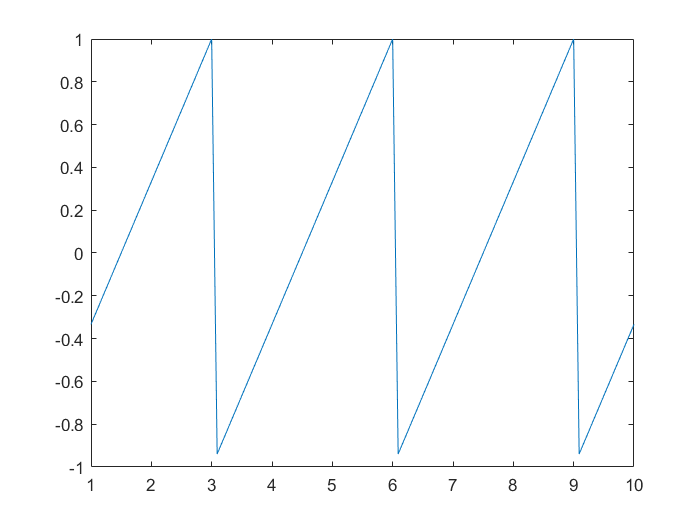

sierra=plot(dominio,imagen);

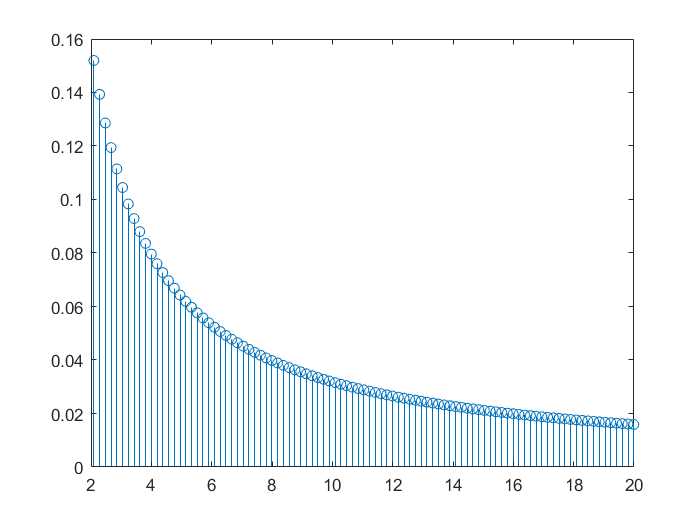


frecuencias = stem(dominioF, imagenF);

xlim([2 20])

function y=sawtooth(x, p,a)
    y=-(2*a/pi)*atan(cot(pi*x/p));
end

function y=amplitud(x, a)
    if (mod(x,2)==1)
         y=-a./(pi*x)
    else
         y=a./(pi*x)
    end
end